Date: 5/15/2020

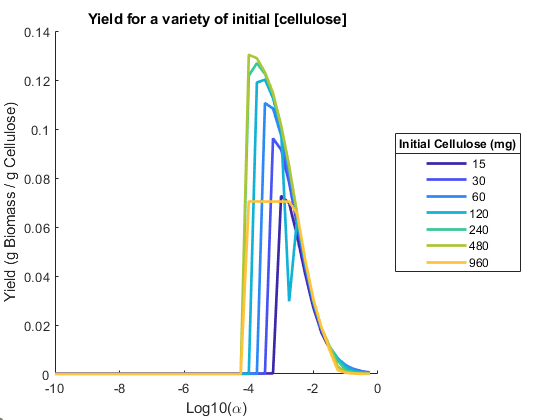

Problem Description: Data for a particular run in pipeline 3 displays a suspicious drop in yield at one point

Data details:

- Cellulolysis kinetic parameters taken from literature

-     KM = 0.2mg/mL, 5.6e-3mM

-     kcat = 32 s^-1

- Initial Mannose is 20x the initial biomass by weight = 0.0150mmoles

- Nongrowth associciated maintenance (NGAM) set to 0.7, GAM set to 23.49

- No initial glucose or enzyme

- Initial population 1.35e-4 g

Data available as diagnosis/DataAnomalies/table_dat3_litparam_growthdropoff.mat

High resolution data available as diagnosis/DataAnomalies/table_dat3_litparam_growthdropoff_ultrahighres.mat

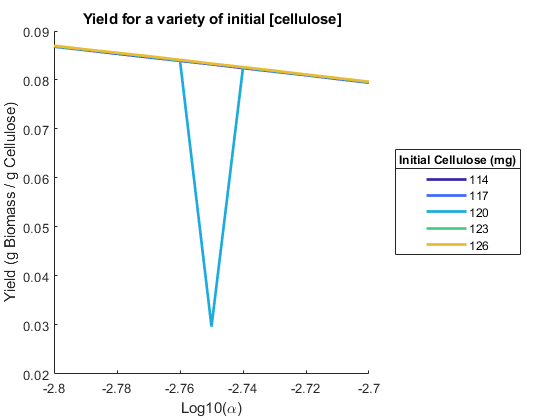

Anomaly is still only present for a single data point.

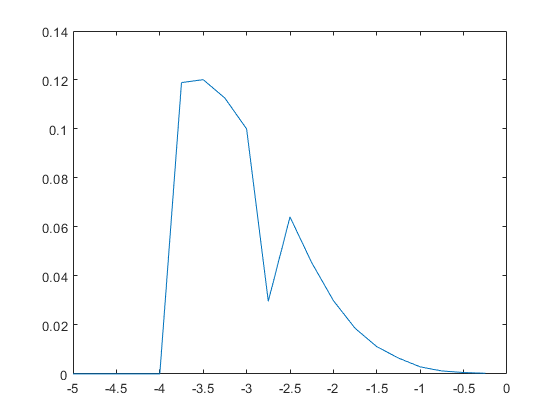

load ("diagnosis/DataAnomalies/table_dat3_litparam_growthdropoff.mat"); %as 't'
plot(log10(t.alpha),t.yield)

rnum = log10(t.alpha)==-2.75;
row = t(rnum,:);

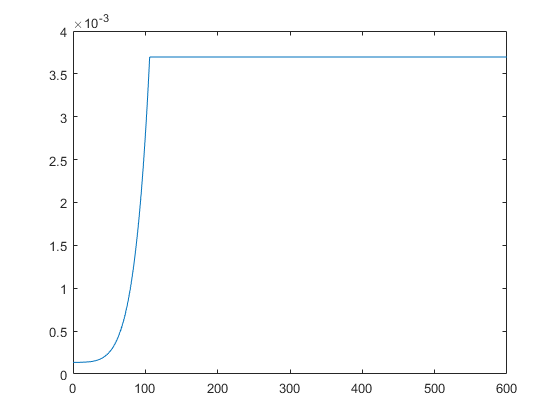

%check growth and media components
plot(row.t{1},row.biomass{1});

plot(row.t{1},horzcat(row.glc_amt{1},row.cellulose_amt{1},row.enzyme_amt{1},row.etoh_amt{1}));
leg = legend({'Glc';'Cel';'Enz';'EtOH'},'location','southoutside','Orientation','horizontal')

leg =   Legend (Glc, Cel, Enz, EtOH) with properties:

         String: {'Glc'  'Cel'  'Enz'  'EtOH'}
       Location: 'southoutside'
    Orientation: 'horizontal'
       FontSize: 9
       Position: [0.2571 0.0952 0.5214 0.0476]
          Units: 'normalized'

  Show all properties


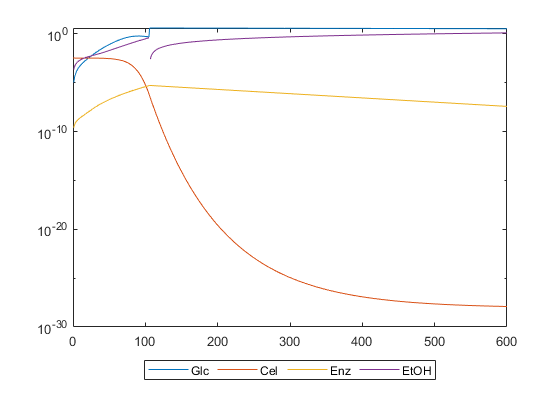

set(gca,'yscale','log');

%get a closer look at glucose and ethanol
plot(row.t{1},horzcat(row.glc_amt{1},row.etoh_amt{1}),'LineWidth',2);
leg = legend({'Glc';'EtOH'},'location','southoutside')

leg =   Legend (Glc, EtOH) with properties:

         String: {'Glc'  'EtOH'}
       Location: 'southoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4455 0.0917 0.1446 0.0869]
          Units: 'normalized'

  Show all properties


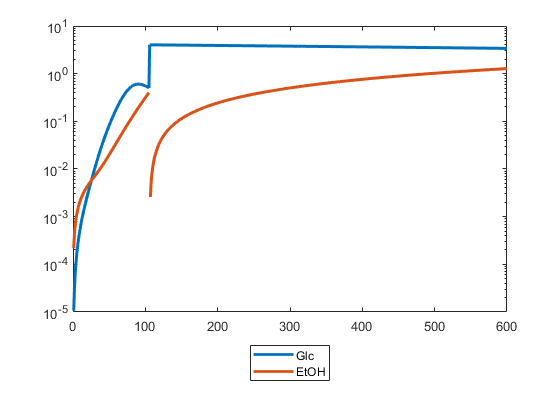

set(gca,'yscale','log');

**Part 1: Run it again, capture the full media**

v = args.p3.v;
v.NGAM = 0.7;
v.GAM = 23.49;
v.kcat_cel = row.kcat_cel(1);
v.km_cel = row.km_cel(1);
v.initcellulose = row.initcel(1);
v.alpha = row.alpha(1);
v.maxcycles = 200;

model = prepareYeastGEMModel('v',v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

layout = buildCelOptLayout(model);

cd 'C:\sync\biomes\cellulose\optima\temp';
runComets(layout);

bio = parseBiomassLog(layout.params.biomassLogName);

Error using countLinesInFile (line 4)
Could not read: C:\sync\biomes\cellulose\optima\temp\log_biomass.m

Error in parseBiomassLog (line 11)
filelength = countLinesInFile(biomassFile);

media = parseMediaLog(layout.params.mediaLogName);

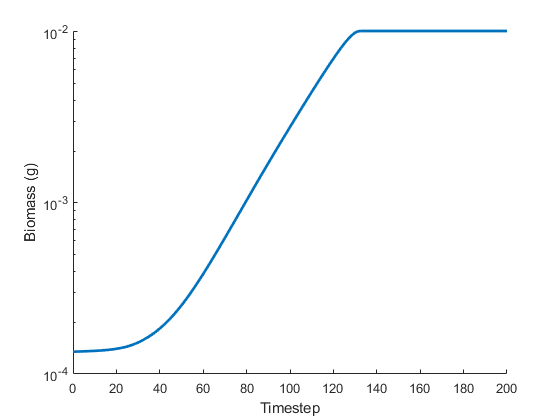

figure();
plotBiomassTimecourse(bio);

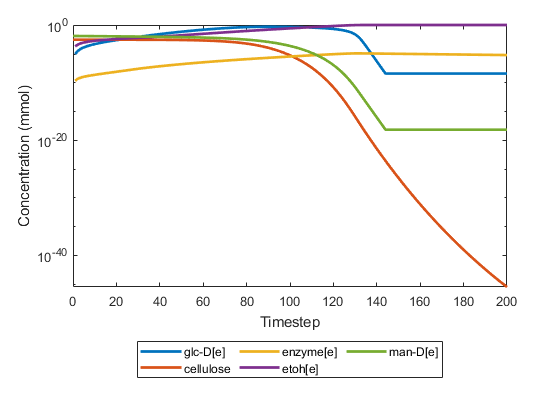

figure();
plotMediaTimecourse(media,{'glc-D[e]','cellulose','enzyme[e]','etoh[e]','man-D[e]',},'l');

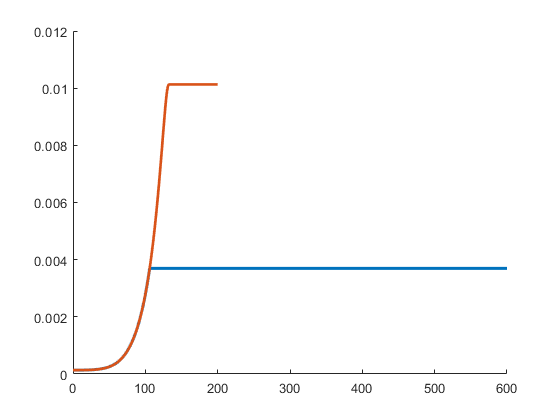

%compare retest vs original
figure();
hold on;
title('Local retest');
plot(row.t{1},row.biomass{1},'linewidth',2);
plot(bio.t,bio.biomass,'linewidth',2);
hold off;

Now it looks like it worked. Rerun with pipeline3, load data for all cell amounts at alpha = 10^-2.75 to confirm consistency of the others

Update: After rerunning pipeline, data still has the same issues

**Part 2: 6/29/2020**

Take the layout/script generated in Part 1, copy it to SCC1, and run it there:

...copying and execution done manually, not shown. Logs copied to /anomalies/ folder with "scc1_" prepended to name.

bio_scc = parseBiomassLog("diagnosis/DataAnomalies/scc1_log_biomass.m");
media_scc = parseMediaLog("diagnosis/DataAnomalies/scc1_log_media.m");

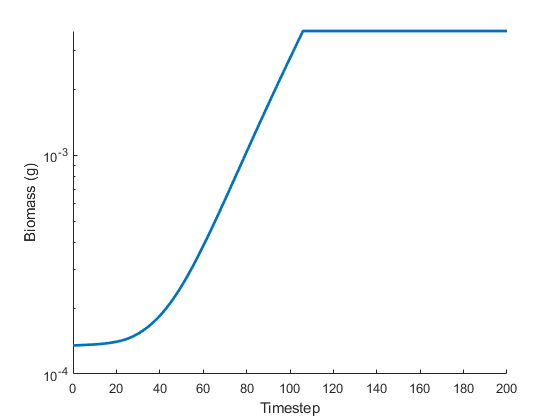

figure();
plotBiomassTimecourse(bio_scc);

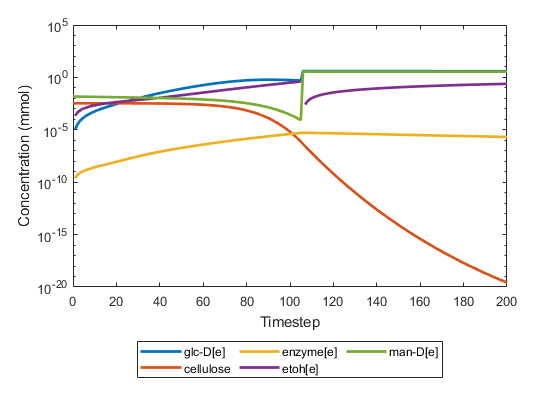

figure();
plotMediaTimecourse(media_scc,{'glc-D[e]','cellulose','enzyme[e]','etoh[e]','man-D[e]',},'l');

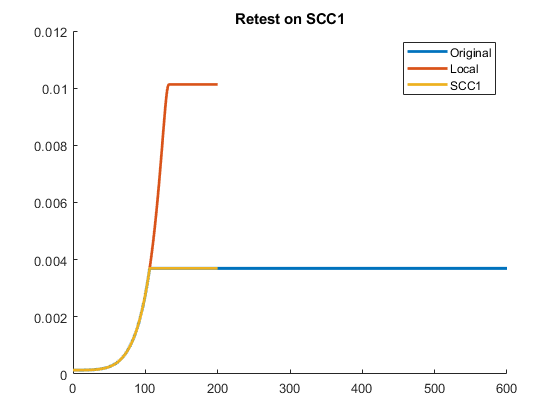

%compare retest vs original
figure();
hold on;
title('Retest on SCC1');
plot(row.t{1},row.biomass{1},'linewidth',2);
plot(bio_scc.t,bio.biomass,'linewidth',2);
plot(bio_scc.t,bio_scc.biomass,'linewidth',2);
leg = legend({'Original';'Local';'SCC1'});
hold off;

SCC1 Retest matches the original, not the local retest.

**Part 3:** Attempt replacing the COMETS JAR on SCC1

old jar moved to ~/archive/comets_branch_comets_branch_2-27-2020.jar on SCC1. Local copy of comets_branch.jar copied to remote ~/comets_branch.jar

bio_scc_B = parseBiomassLog("diagnosis/DataAnomalies/scc1_B_log_biomass.m");
media_scc_B = parseMediaLog("diagnosis/DataAnomalies/scc1_B_log_media.m");

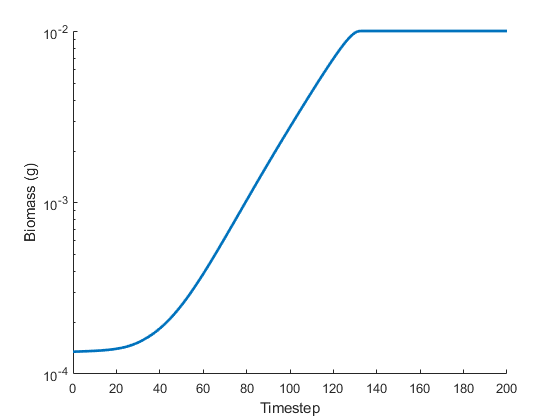

figure();
plotBiomassTimecourse(bio_scc_B);

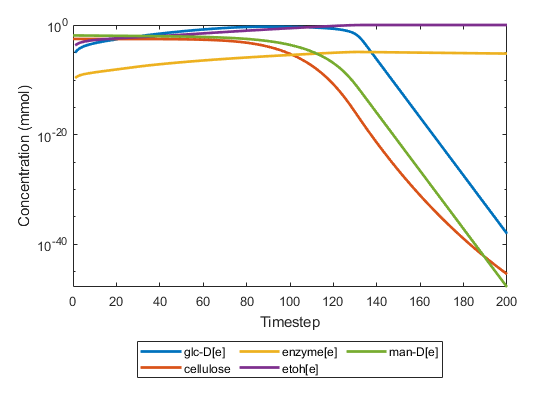

figure();
plotMediaTimecourse(media_scc_B,{'glc-D[e]','cellulose','enzyme[e]','etoh[e]','man-D[e]',},'l');

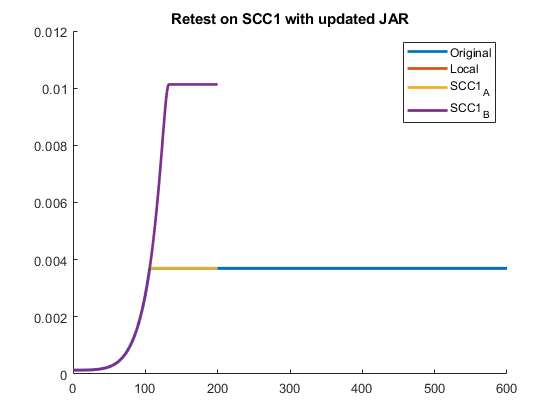

%compare retest vs original
figure();
hold on;
title('Retest on SCC1 with updated JAR');
plot(row.t{1},row.biomass{1},'linewidth',2);
plot(bio_scc.t,bio.biomass,'linewidth',2);
plot(bio_scc.t,bio_scc.biomass,'linewidth',2);
plot(bio_scc.t,bio_scc_B.biomass,'linewidth',2);
leg = legend({'Original';'Local';'SCC1_A';'SCC1_B'});
hold off;